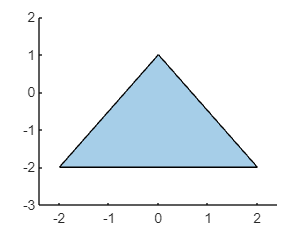

path_verts =polyshape([-2,2,0],[-2,-2,1]);
plot(path_verts);

verts = [[-2,2,0];[-2,-2,1]]';
line_int(verts,@(x,y) -y/2, @(x,y) x/2)

ans = 0

line_int(verts,@(x,y) -y/2, @(x,y) x/2)

ans = 0



area(path_verts)

ans = 6

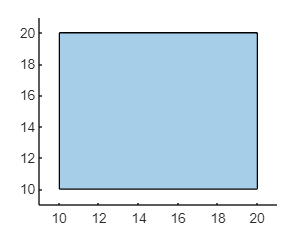

quad_vertex = [10 10; 20 10; 20 20; 10 20];
plot(polyshape(quad_vertex(:,1),quad_vertex(:,2)))

line_int(quad_vertex,@(x,y) -0.5*y.^2, @(x,y) 0*x)

ans = 0

centroid(polyshape(quad_vertex(:,1),quad_vertex(:,2)))

ans = 15

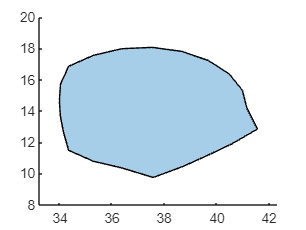

polyg = bots(3).verts_unc;
polg = polyshape(polyg(1,:),polyg(2,:));
plot(polg)

centroid(polg)

ans = 37.4791

line_int(polyg,@(x,y) 0*x, @(x,y) 0.5.*x.^2)/line_int(polyg,@(x,y) 0*x, @(x,y) x)

ans = 37.4791

poly2ccw(polyg(1,:),polyg(2,:))

ans =    40.9792   40.4736   39.6810   38.6719   37.5359   36.3739   35.2892   34.3472   34.0367   33.9953   34.0304   34.1470   34.3466   35.2892   36.3739   37.5753   38.7051   39.6470   40.5787   41.5525   41.1528


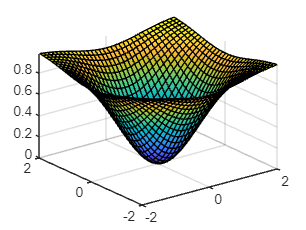

x = sym('x');
y = sym('y');
cov = sym('c',[2,2]);
cov = [1,0;0,1];
pro_g = matlabFunction(sym((1-exp(-1/2*[x;y]'*inv(cov)*[x;y]))));
fsurf(pro_g,[-2 2 -2 2])

dist_rev=sym((1-exp(-1/2*[x;y]'*inv(cov)*[x;y])))

$$dist\_rev = 1-{\mathrm{e}}^{-\frac{x\,\bar{x}}{2}-\frac{y\,\bar{y}}{2}}$$

f_mass = int(dist_rev,x)

$$f\_mass = x-\frac{\sqrt{2}\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{y\,\bar{y}}{2}}\,\mathrm{erf}\left(\frac{\sqrt{2}\,x}{2}\right)}{2}$$

f_cent=int(x*dist_rev,x)

$$f\_cent = {\mathrm{e}}^{-\frac{x^{2}}{2}-\frac{y\,\bar{y}}{2}}+\frac{x^{2}}{2}$$

line_int(polyg,@(x,y) 0*x,matlabFunction(f_cent))/line_int(polyg,@(x,y) 0*x, matlabFunction(f_mass))

ans = 37.4791

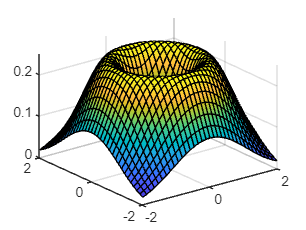

fsurf(matlabFunction(dist_rev*(-sym(pro_g)+1)),[-2 2 -2 2])

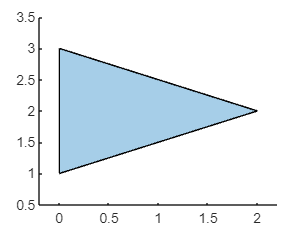

a=[0,2,0];
b = [1,2,3];
c = polyshape(a,b);
plot(c)

plot(polyshape(bots(1).obst(1,:),bots(1).obst(2,:)))

Index in position 1 exceeds array bounds.

figure 
hold on
plot(bots(3).obst(1,:),bots(3).obst(2,:))
plot(bots(3).verts(1,:),bots(3).verts(2,:))


a = intersect(polyshape(bots(3).verts(1,:),bots(3).verts(2,:)),polyshape(bots(3).obst(1,:),bots(3).obst(2,:)))


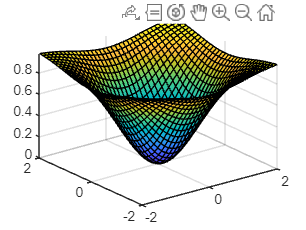

syms x y
rs = 2.0;
pos = 0.0;
fun = matlabFunction(1-exp(-1/2*(pos - [x;y])'*inv([rs/2 0;0 rs/2])*(pos - [x;y])));
fsurf(fun,[-rs rs -rs rs])

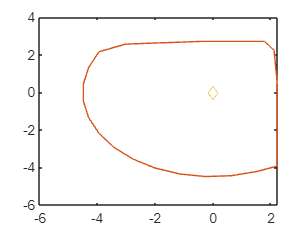

a = bots(1).verts_unc - bots(1).pos;

polyrr = polyshape(a(1,:),a(2,:));
hold on
plot([a(1,:),a(1,1)],[a(2,:),a(2,1)])
plot(0,0,'d')
hold off